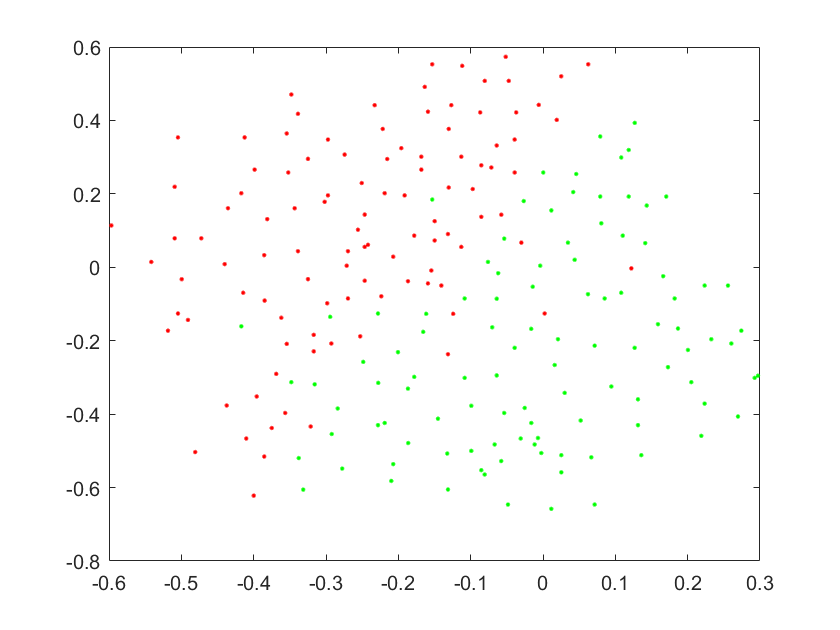

data = readmatrix('data5\data5\training_3.txt');

dataSize = size(data, 1);

feature1 = data(:, 1);
feature2 = data(:, 2);
features = [feature1, feature2];
labels = data(:, 3);

class1_indices = find(labels == 1);
class2_indices = find(labels == -1);

figure;
plot(feature1(class1_indices), feature2(class1_indices), 'r.');
hold on;
plot(feature1(class2_indices), feature2(class2_indices), 'g.');
hold on;


% Gaussian Kernel Calculation using pdist2 function
gamma = 100;
k = exp(-gamma * pdist2(features, features, 'euclidean').^2);

H = labels * labels' .* k;

f = -ones([1, dataSize])';

Aeq = labels';

beq = 0;

c = 1;
upper_bound = c .* ones([dataSize, 1]);

lower_bound = zeros([dataSize, 1]);

[my_ans, f_val] = quadprog(H, f, [], [], Aeq, beq, lower_bound, upper_bound);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


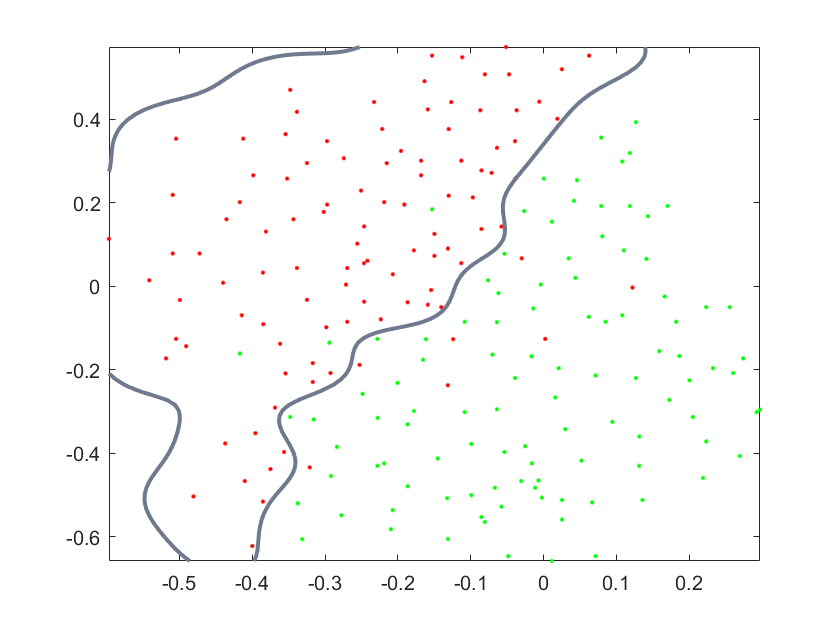


support_vectors_indices = find(my_ans > 1e-5);

support_vectors_x = features(support_vectors_indices, :);
support_vectors_y = labels(support_vectors_indices);

len = length(support_vectors_indices);
sum_b = 0;
for i = 1:len
    sum_alpha = 0;
    for j = 1:dataSize
        sum_alpha = sum_alpha + my_ans(i) * labels(i) * k(i, j);
    end
    sum_b = sum_b + support_vectors_y(i) - sum_alpha;
end

bias = sum_b / len;

x_plot = linspace(min(features(:, 1)), max(features(:, 1)), 100)';
y_plot = linspace(min(features(:, 2)), max(features(:, 2)), 100)';
[xx, yy] = meshgrid(x_plot, y_plot);
vals = zeros(size(xx));
for i = 1:length(vals)
    for j = 1:length(vals)
        x2 = [xx(i, j), yy(i, j)];
        temp = 0;
        for k = 1:dataSize
            temp = temp + my_ans(k) * labels(k) * exp(-gamma * ((features(k, 1) - x2(1))^2 + (features(k, 2) - x2(2))^2));
        end
        vals(i, j) = temp + bias;
    end
end

colormap bone;
contour(xx, yy, vals, [0 0], 'LineWidth', 2);